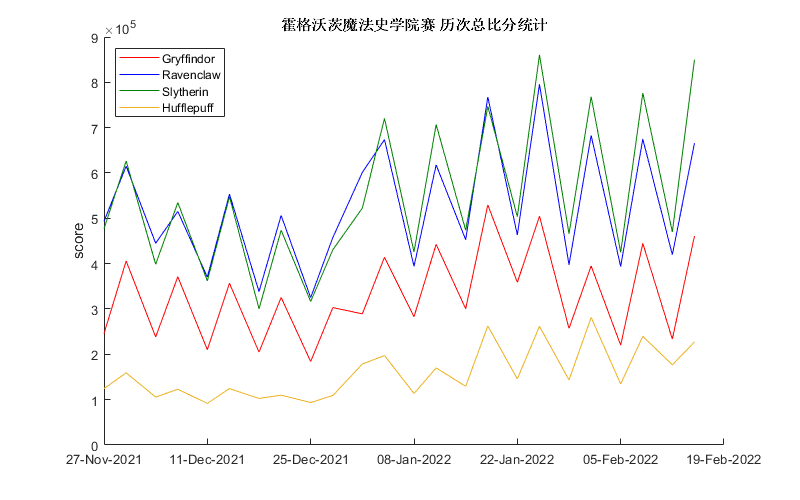

clc
clear all

currentFolder = pwd;                            % set wd to current folder

CellExcel  = '霍格沃茨魔法史学院赛总比分A.xlsx';    % read in excel cell file

[raw] = readcell(CellExcel);
headers    = raw(1, :);                         % separate headers
raw(1, :)  = [];                                % remove headers

CellTable  = cell2table(raw(:, 1:length(headers)), 'VariableNames', headers); % combine headers & data into cell table array
G1 = groupfilter(CellTable,'score',@(x) all(x == "Gryffindor"),'house');
G2 = groupfilter(CellTable,'score',@(x) all(x == "Ravenclaw"),'house');
G3 = groupfilter(CellTable,'score',@(x) all(x == "Slytherin"),'house');
G4 = groupfilter(CellTable,'score',@(x) all(x == "Hufflepuff"),'house');

figure(1)
plot(G1.date,G1.score,'r')
hold on
plot(G2.date,G2.score,'b')
plot(G3.date,G3.score,'color',[0 .5 0])
plot(G4.date,G4.score,'color',[0.9290, 0.6940, 0.1250])
hold off
legend('Gryffindor','Ravenclaw','Slytherin','Hufflepuff','Location','northwest')
ylabel('score')
title('霍格沃茨魔法史学院赛 历次总比分统计')

box off

set(gcf,'position',[0,0,800,500])